# Affichage de Trajectoire 

Ce programme permet d'afficher les différentes trajectoires de l'expérience 2 suivant différent critères : par angle de redirection, par participants, par cible.

### chargement des données :

Les données de trajectoire, d'angle de redirection, de position des cibles ont été préalablement stocké dans des matrices pour chaque participants, nous les chargeons ici :

CandidatPosition = [10,11,12,13,14,15,16,18,19,20,21];
TargetNumberGlobale = load('TargetNumberGlobal','TargetNumberGlobal');
TargetNumberGlobal = TargetNumberGlobale.TargetNumberGlobal;
RedirectionAngleGlob = [];
IndiceGlob = ones(239,4,length(CandidatPosition));
l =4

l = 4


    k = CandidatPosition(l);
    iStr = int2str(k);

    
    filename = strcat('Data/RedirectionAngle/RedirectionAngle',iStr);
    filename = strcat(filename,'.mat');
    RedirectionAnglee = load(filename,'RedirectionAngle');
    RedirectionAngle = RedirectionAnglee.RedirectionAngle;
    RedirectionAngleGlob = [RedirectionAngleGlob RedirectionAngle]; 
    
    filename = strcat('Data/Trajectoire/Trajectoire',iStr);
    filename = strcat(filename,'.mat');
    Trajectoiree = load(filename,'Trajectoire');
    Trajectoire = Trajectoiree.Trajectoire;
    
    filename = strcat('Data/Indice/Indice',iStr);
    filename = strcat(filename,'.mat');
    Indicee = load(filename,'Indice');
    Indice = Indicee.Indice;
    IndiceGlob(:,:,k) = Indice;
    
    filename = strcat('Data/centreDesTargets/centreDesTargets',iStr);
    filename = strcat(filename,'.mat');
    centreDesTargetse = load(filename,'centreDesTargets');
    centreDesTargets = centreDesTargetse.centreDesTargets;


### Affichage par angle :

    
    Angle = [-0.226892800000000,-0.174532900000000,-0.139626300000000,-0.104719800000000,-0.0872664700000000,-0.0698131700000000,-0.0349065800000000,0,0.0349065800000000,0.0698131700000000,0.0872664700000000,0.104719800000000,0.139626300000000,0.174532900000000,0.226892800000000];
    NumAngle = 4

NumAngle = 4

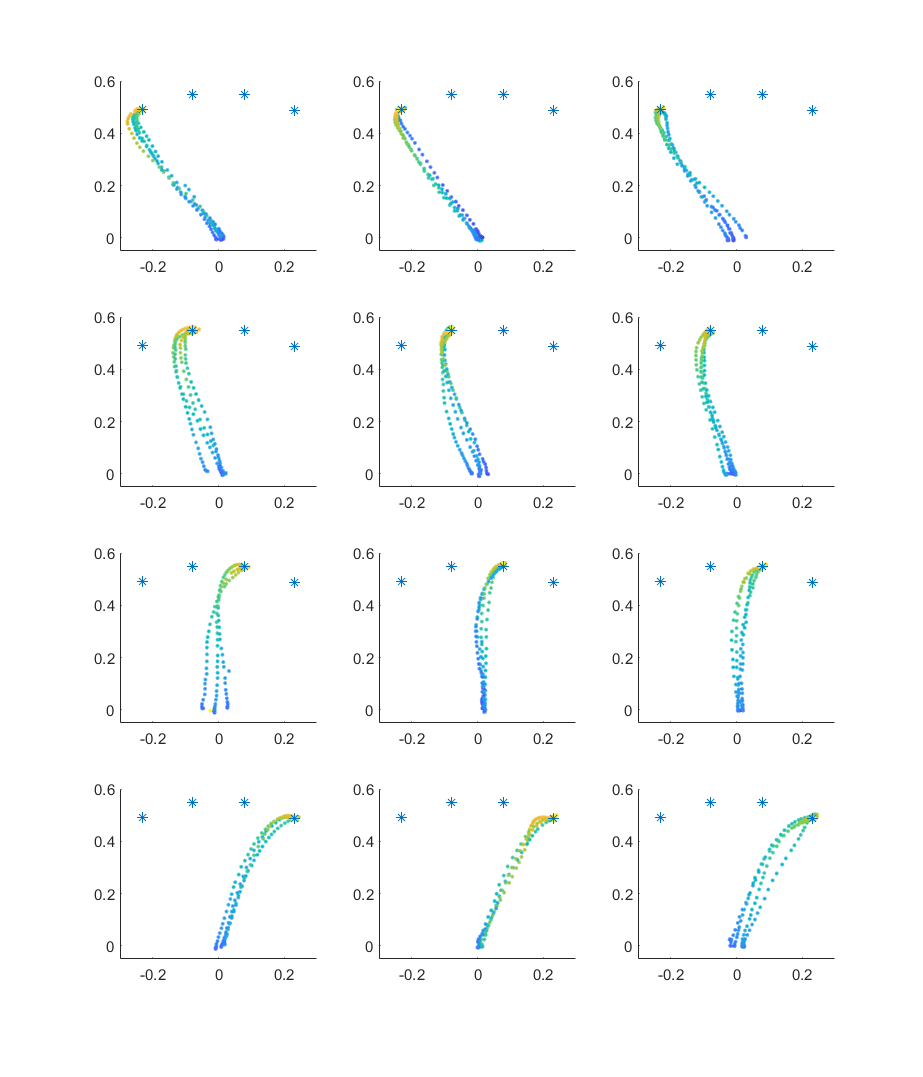

    angle = Angle(NumAngle);
    figure("position",[0 0 1200 1400])
    for target = 0:1:3

        previous = 1;
        for i=1:1:239
            
            NombreDePoints = Indice(i,3)-Indice(i,1);
            NombreDePointsT = Indice(i,4)-Indice(i,1);
            if RedirectionAngle(i)==angle && TargetNumberGlobal(i,l)==target
                subplot(4,3,3*(target)+2)
                c = linspace(1,10,length(Trajectoire(previous:previous+NombreDePointsT,1)));
                scatter(Trajectoire(previous:previous+NombreDePointsT,1),Trajectoire(previous:previous+NombreDePointsT,2),[],c,'.')
                hold on
                scatter(centreDesTargets(:,1),centreDesTargets(:,2),'*')
                hold on
                xlim([-0.3 0.3])
                ylim([-0.05 0.6])
            end
            if NumAngle>1
                if RedirectionAngle(i)==Angle(NumAngle-1) && TargetNumberGlobal(i,l)==target 
                    subplot(4,3,3*(target)+1)
                    c = linspace(1,10,length(Trajectoire(previous:previous+NombreDePointsT,1)));
                    scatter(Trajectoire(previous:previous+NombreDePointsT,1),Trajectoire(previous:previous+NombreDePointsT,2),[],c,'.')
                    hold on
                    scatter(centreDesTargets(:,1),centreDesTargets(:,2),'*')
                    hold on
                    xlim([-0.3 0.3])
                    ylim([-0.05 0.6])
                end
            end
            if NumAngle<15
                if RedirectionAngle(i)==Angle(NumAngle+1) && TargetNumberGlobal(i,l)==target
                    subplot(4,3,3*(target)+3)
                    c = linspace(1,10,length(Trajectoire(previous:previous+NombreDePointsT,1)));
                    scatter(Trajectoire(previous:previous+NombreDePointsT,1),Trajectoire(previous:previous+NombreDePointsT,2),[],c,'.')
                    hold on
                    scatter(centreDesTargets(:,1),centreDesTargets(:,2),'*')
                    hold on
                    xlim([-0.3 0.3])
                    ylim([-0.05 0.6])
                end
            end
            previous = previous +NombreDePoints+1;
            
                
        end
        hold off
    end

   k = 6

k = 6

COVA =   -10.9190   -2.5683   -0.0078   -9.8021   -2.3451    0.3162   -9.2672   -2.4497    0.6210  -10.1033   -2.7115    0.5369  -10.1452   -2.0478    0.6940   -9.8439   -2.4474   -1.2435   -0.0234    0.0164    0.0146   -0.0127    0.0002    0.0027   -0.0344    0.0201    0.1253   -0.0044   -0.0872    0.0154   -0.0258   -0.0070    0.0812    0.0073    0.0398   -0.0183    0.1137    0.3206    0.5583    0.1809    0.5536    0.0109
  -10.3667   -1.9466   -0.2954   -8.2414   -3.2726    0.1158   -9.8398   -2.0448    0.5678  -11.2894   -2.0339    0.6000   -9.8595   -2.6989    0.2825   -8.6666   -1.7972   -0.4303   -0.0152   -0.0092    0.0120    0.0151   -0.0049   -0.0155   -0.0422    0.0092    0.2668    0.0052   -0.0435    0.0081   -0.0260   -0.0198    0.0567    0.0049    0.0737   -0.0004    0.2494   -0.0058    0.4858    0.2724    0.4548   -0.0763
  -10.9982   -2.0954   -0.7812   -8.6352   -1.9771   -1.3012  -10.1930   -2.0296    1.2622   -9.8589   -2.7046   -0.6292   -8.9136   -2.3716    0.3107 

nbrBootstrap = 100

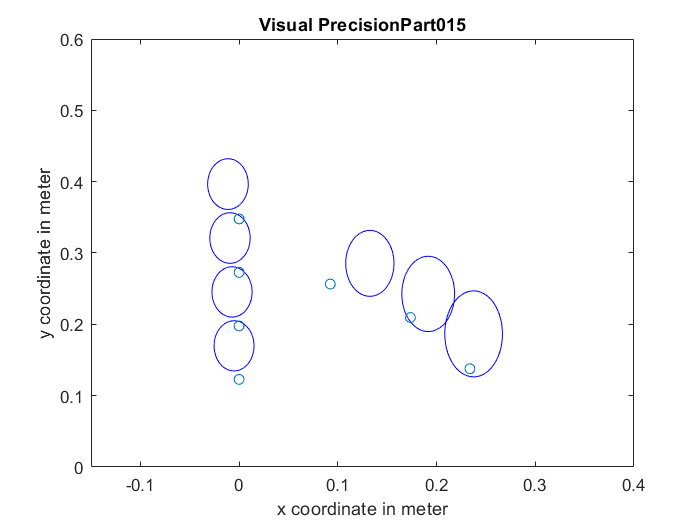

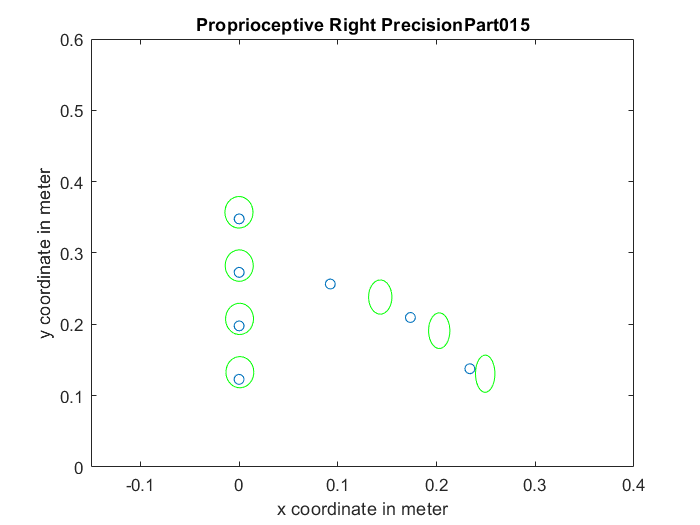

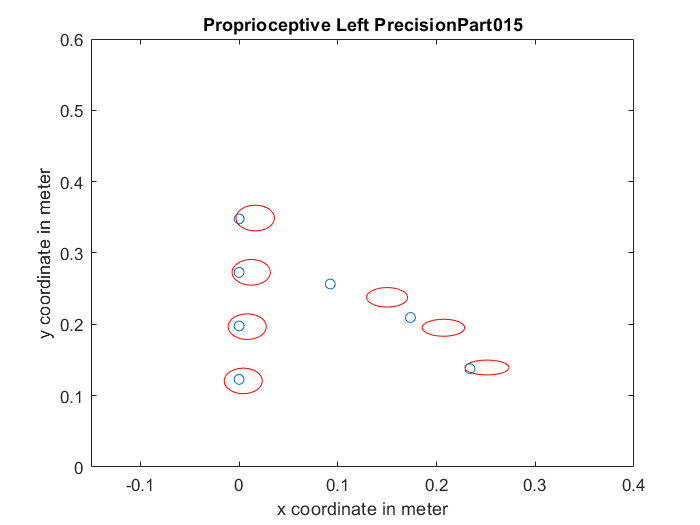

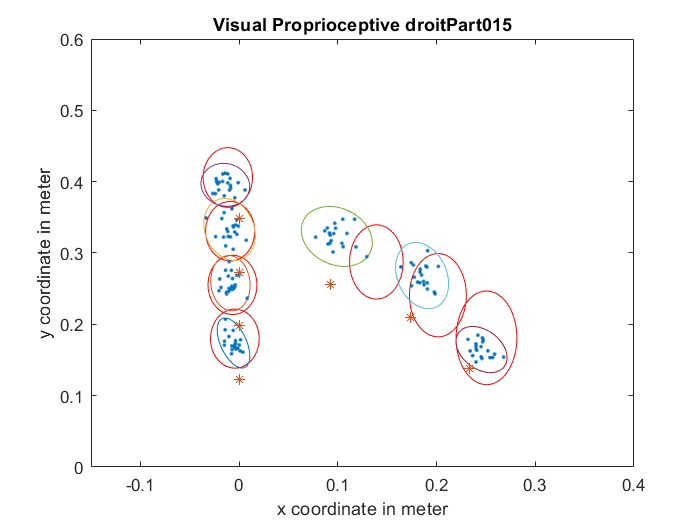

valadd = 139.5488

valadd = 130.5767

valadd = 123.2350

valadd = 131.3560

valadd = 117.5227

valadd = 121.5632

valadd = 130.1978

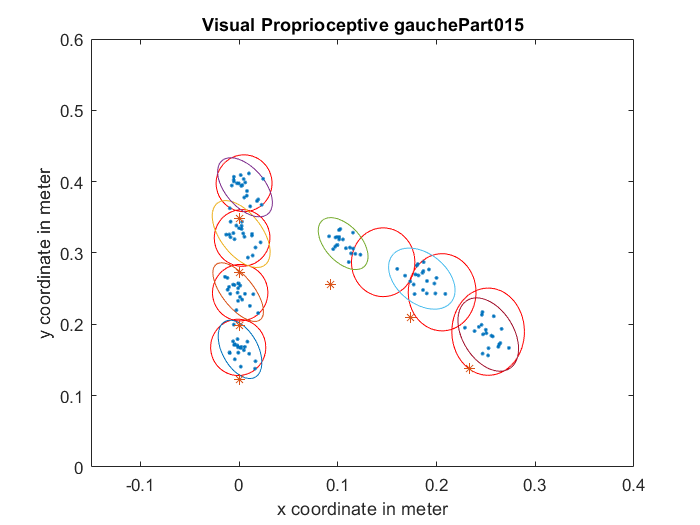

valadd = -Inf

valadd = -1.2830e+04

valadd = -6.7881e+03

valadd = -7.0073e+03

valadd = -2.9934e+03

valadd = -363.5987

valadd = 117.8506

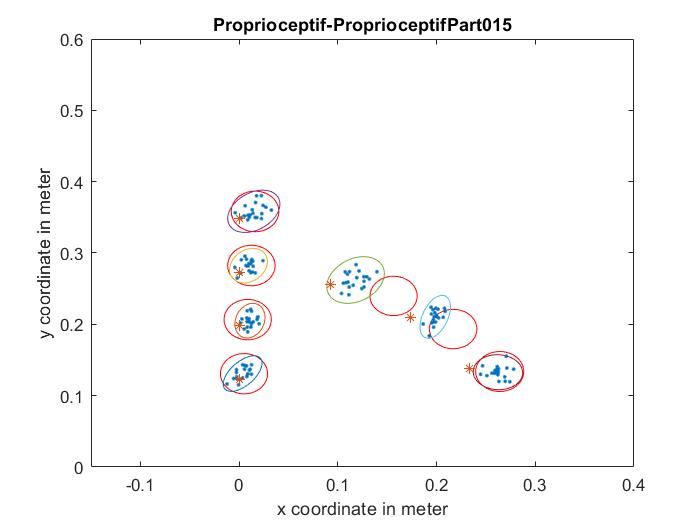

valadd = -Inf

valadd = -Inf

valadd = -Inf

valadd = -Inf

valadd = -4.8603e+03

valadd = -3.6896e+03

valadd = 135.0712

   plotDesDistriUniEasy(k)